# Week 9: Configuration Space

*Author: Keith Chester*

*E-mail: kchester@wpi.edu*

## Introduction

In this week's assignment, we are looking to create an interactive exploration of cartesian, task, and configuration spaces. We aim to explore these spaces, how to generate them, and consider how to utilize them for path planning in future work.

## Methods

We operate primarily within cartesian space - it is how we view the world. As such, we wish for the robot to operate in cartesian space as well - find paths between two positions, move the end effector around within it, and avoid obstacles specified within it. It is far easier, however, to perform many of these actions when considering the robot in alternative spaces, such as task and configuration spaces.

### Collision Detection

First we consider collision detection. How do we dtermine if a link of our robot arm has collided with an obstacle in a given configuration.

To do this, we will make use of circle collision detectors. For a given link of a robot arm, take its start and end point. Draw a circle around these points by finding the midpoint between them. The radius of the circle is the distance from either point to the midpoint. Using the midpoint as a new "edge", create two more circles between the two halves of the links. Do this, repeatedly, to a preset depth.

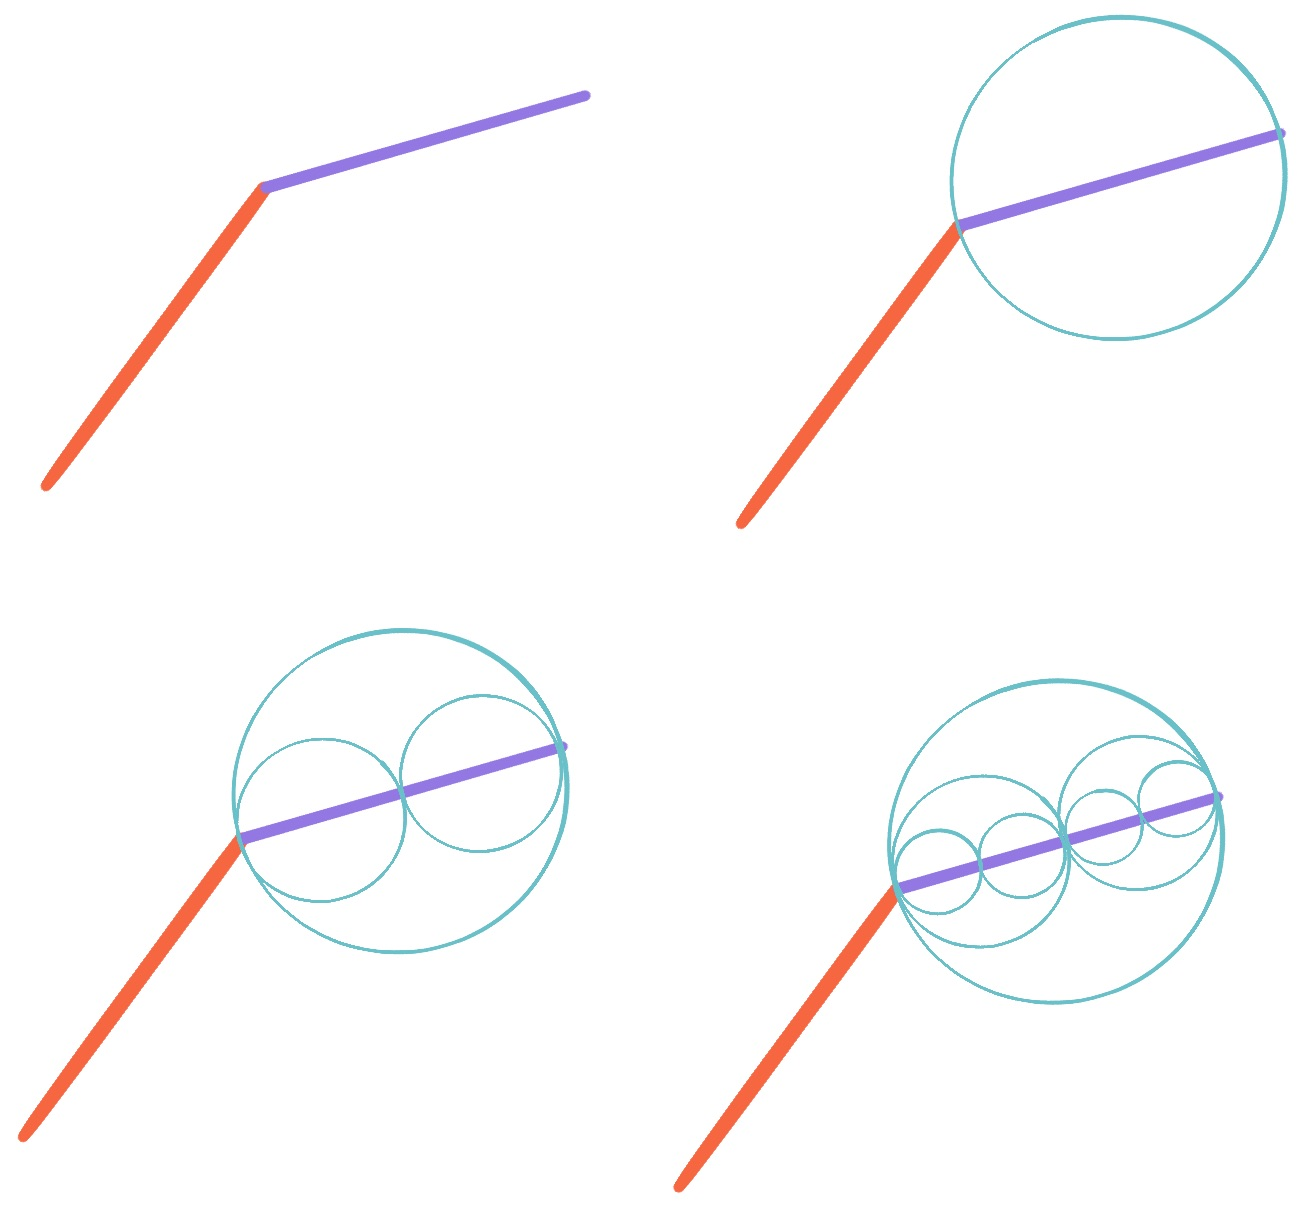

*Figure 1: Generating Collision Detection Circles to an Arm Link*

We can perform the same action on each edge of the polygons that represent obstacles. Due to time constraints, we simplified here and used circle obstacles, however.

When doing collision tests, we can check to see if the largest circle of ecah link collides with any from a given obstacle. This check is very quick computationally, and can be done for many, many obstacles quickly. If the outermost circle does not collide with anything, then we know the link does not collide. If it does intersect, we move down into higher depth circles, checking them recursively. Finally, we consider a link collided with an obstacle if the smallest circles at the highest depth intersect with the obstacle.

### Task Space and Configuration Space Generation

To generate the task space, we take our two joint values of theta1 and theta2, and sweep them through values of 0 to $2\pi$. The number of increments between this range we label as a given "resolution". For each step of theta1, we move through the whole range of theta2 possibles. This results in ${\textrm{resolution}}^2$ steps. At each step, we check to see if any part the arm, from base to tip, collides with with any obstacles in cartesian space. If it does, we make note of the configuration and x/y location of the end effector.

We then can create a mapping of the task space by taking our noted end effector positions, and marking collision-free spots within our given range of our cartesian space. This results in a mapping of locations our end effector can safely reach. Note that we are careful not to mark down collision spaces. Without additional processing, this will show some areas as both collision-free and collided. This is because the end effector can reach areas with multiple configurations, and come of those configurations might cause a link collision, where as others don't. This can result in confusion over whether an end effector position is actually possible.

We can also generate the configuration map from this sweep, as we recorded the collision status and the theta1 and theta2 values during the sweeps. From this, we can create a plot of theta1 vs theta2 values and plot whether or not a collision occured in the given space. This gives us a map of all possible configurations and hte subset of which would cause collisions for our robot arm.

### An Alternative: Probablistic Roadmaps (PRM)

Note that the process of "sweeping" the joints of theta1 and theta2 is expensive - ${\textrm{resolution}}^2$. If we begin to add additional joints to our robot arm, the dimensionality of the arm explodes the complexity off "sweeping" to generate the data needed to map the configuration space. Specifically, it becomes a case of ${\textrm{resolution}}^n$ where *n* is the number of dimensions/joints we must consider. This becomes unfeasible quickly.

An alternative solution is to utilize PRM - which generates a rough roadmap of the configuration space, which can be "good enough" for most applications. This is acheived by sampling configurations randomly and then marking their collision result. Over a large enough sampling, a rough shape of collisions detectable and the map generated far quicker than performing a "sweep" across all joints.

### Uses for Alternative Spaces

These alternative spaces provide quick answers for several robot arm motion planning problems. The task space can be utilized to determine if a given desired end effector position can be safely reached in any configuration. It can also be used to determine if a path exists between a start and desired end effector position via a path planning algorithm.

The configuration space can tell you if a given robot configuration collides with environment obtsacles or not. It can be utilized with a path planning algorithm to create a complete trajectory of movements for each robot joint to move from one configuration to another and move the end effector into a desired position.

## Results

We have created an interactive demonstration of collision detection in cartesian space to generate both task and configuration spaces.

### Generating Obstacles

First, we **open an interactive window **to draw obstacles for the robot. If no obstacles are drawn, we will utilize a default set of obstacles. The interactivty of this agent is at times suspect, so ensure that the window looks like this before continuing.  If it doesn't, close the window and re-hit the button to draw obstacles.

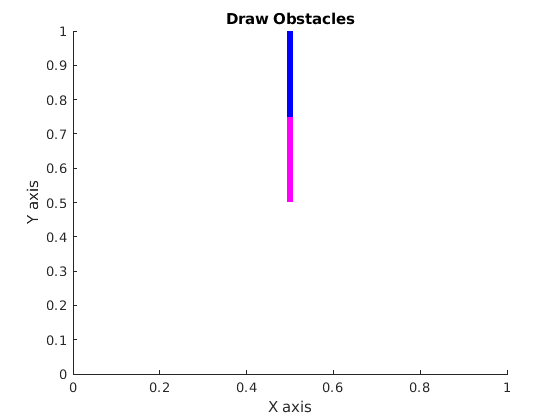

*Figure 2: Expected start condition - our robot arm extends from (0.5, 0.5), and looks upward*

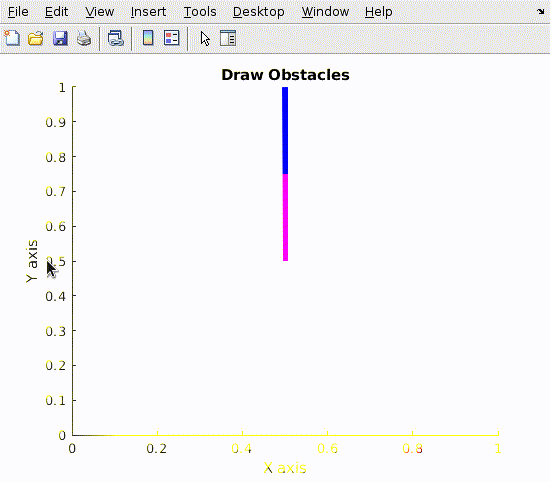

*Figure 3: A demonstration of adding obstacles to our cartesian space*

In this example, our robot arm originates in the middle of our figure (0.5,0.5) - each link is 0.25m long, and our plot is a 1mx1m square.

 
clc
f = figure();
arm_lines = draw_robot_arm(pi/2, pi/2);
hold on;
axis manual
axis([0 1 0 1])
set(gcf,'Visible','on')
set(f, 'WindowButtonDownFcn',{@user_obstacle_draw})
set(f, 'WindowButtonMotionFcn', @mouse_move)
title("Draw Obstacles")
ylabel("Y axis")
xlabel("X axis")


global current_polygon
current_polygon = [];
global obstacles
obstacles = {};
global active_center
active_center = false;
global active_line
active_line = false;

Once you have drawn your obstacles, hit the below button to save them and output our graph.

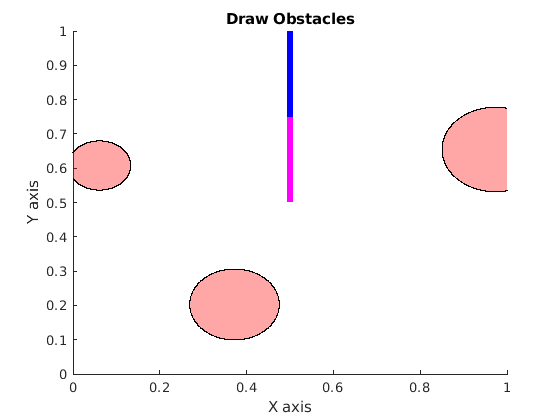

 
hold off;

if length(obstacles)
    obsstacles = {
        struct('center', [0.1913; 0.6968], 'radius', 0.0940),
        struct('center', [0.3439, 0.2629], 'radius', 0.0619),
        struct('center', [0.8486, 0.5216], 'radius', 0.1002)
    };
end

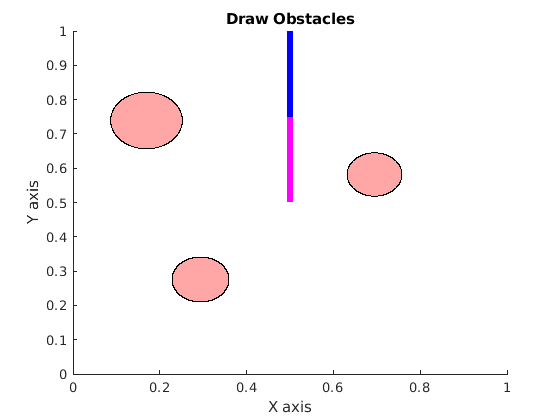

*Figure 4: An example of cartesian space after drawing our obstacles*

As we mentioned before, we will be utilizing recursive circle detectors on each limb. We discussed doing so for polgon obstacles, but in the interest of time we will be just utilizing circle obstacles for now.

Each limb is divided up into increasing "depth" of circles - for each layer of depth there is $2^{\textrm{depth}-1}$circles. The largest circle encompasses the entire link, and each increasing depth level covers a smaller subsection of the arm. We go 4 levels deep, providing a relatively close coverage of the link.

These detectors are used to pick up collisions. If the outermost circle does not detect a collision, then the obstacle and the link absolutely do not collide. If the circle does overlap, we check all the circles of the following depth. If we detect any collisions at the fourth and final depth, then we consider the link as having collided with the obstacle.

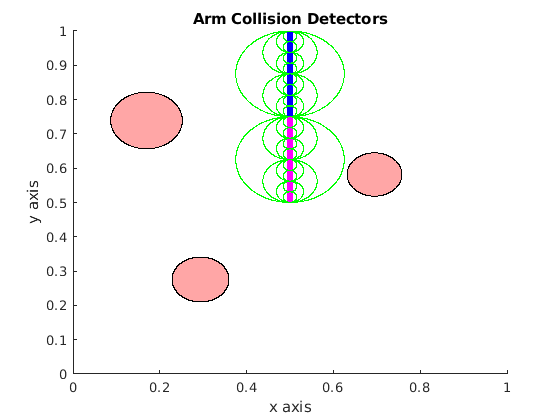

*Figure 5: The arm's collision detectors drawn onto the arm for reference*

Here we draw the arm with obstacle detectors drawn around it:

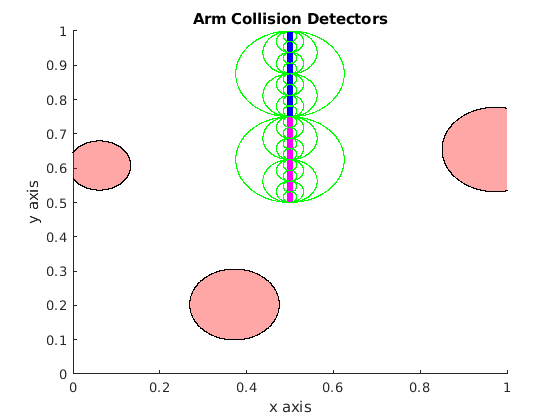

 
arm_collision_circles = figure();
title("Arm Collision Detectors")
ylabel("y axis")
xlabel("x axis")
axis([0 1 0 1])
hold on;
limb_length = 0.25; % meters
origin = [0.5; 0.5];
j1 = [origin(1)+limb_length*cos(pi/2); origin(2)+limb_length*sin(pi/2) ];
j2 = [j1(1)+limb_length*cos(pi/2); j1(2)+limb_length*sin(pi/2) ];

new_lines = draw_robot_arm(pi/2, pi/2);
arm_lines = {};
for line = 1:length(new_lines)
    arm_lines{end+1} = new_lines(line);
end

% Draw a circle for each part of the line
%%%%%%%%% Joint 1
a_circles = limb_collision_circles(origin, j1);
%%%%%%%%% Joint 2
b_circles = limb_collision_circles(j1, j2);
circles = cat(2, a_circles, b_circles);
for index = 1:length(circles)
    draw_circle(circles{index});
end
for index = 1:length(obstacles)
    draw_obstacle(obstacles{index});
end
hold off;

### Generating the Task and Configuration Spaces

We are going to sweep through 0 to $2\pi$for each joint at an increment we'll label called *resolution*. IE - for a given sweep, there are 25 points we check between, and including, 0 and $2\pi$. We allow increasing the resolution to 100, but this increases our computation time up to a minute. The increased resolution adds significantly more data points making our charts look more "complete" - though even at a resolution of 25 we can get an excellent idea of what our spaces are.

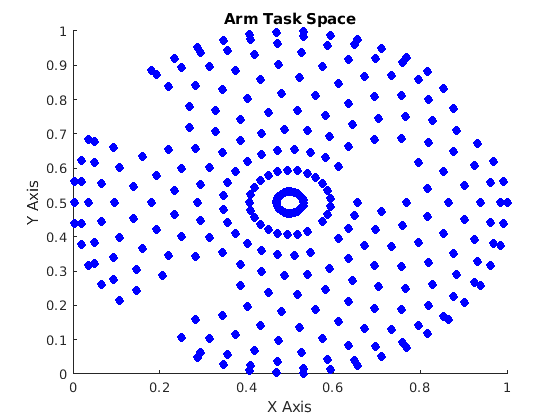

*Figure 6: An example task space with resolution of 25. Blue dots represent possible collision-free end effector locations. Obstacles and limited reaching is observable even with the lowest resolution setting.*

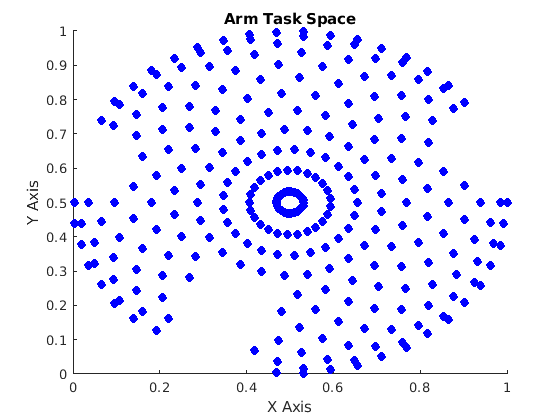

resolution = 25;
 

space = zeros([5, resolution]);
step = 0;
for theta1 = 0:(2*pi)/resolution:2*pi
    for theta2 = 0:(2*pi)/resolution:2*pi
        j1 = [origin(1)+limb_length*cos(theta1); origin(2)+limb_length*sin(theta1) ];
        j2 = [j1(1)+limb_length*cos(theta2); j1(2)+limb_length*sin(theta2) ];
        
        collision = collisions_for_joint(origin, j1, obstacles);
        % Only check for the j2 collison if we failed to find one for j1
        if ~collision
            collision =collisions_for_joint(j1, j2, obstacles);
        end
        
        step = step + 1;
        space(1,step) = theta1;
        space(2,step) = theta2;
        space(3,step) = j2(1);
        space(4,step) = j2(2);
        space(5,step) = collision;
    end
end

task_space = figure();
title("Arm Task Space")
ylabel("Y Axis")
xlabel("X Axis")
axis([0 1 0 1])
hold on;

task_free_spaces = space(3:4,space(5,:)==false);
plot(task_free_spaces(1,:), task_free_spaces(2,:), 'o', 'MarkerFaceColor','blue','MarkerEdgeColor','blue');
hold off;

Here we generate our configuration space for the arm, using the data generated while sweeping to generate the task space above.

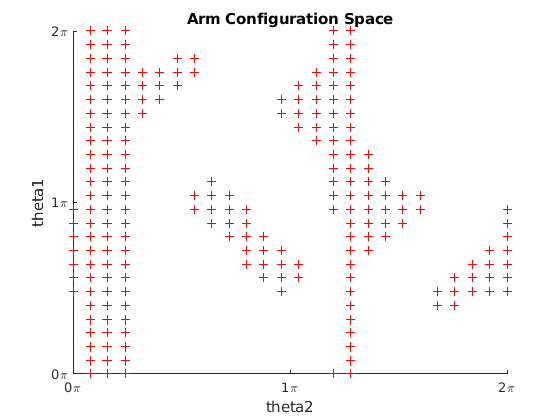

*Figure 7: Example configuration space for a given set of obstacles and our robot arm. The red crosses represent areas of collision, whereas white space represent open, free areas of movement.*

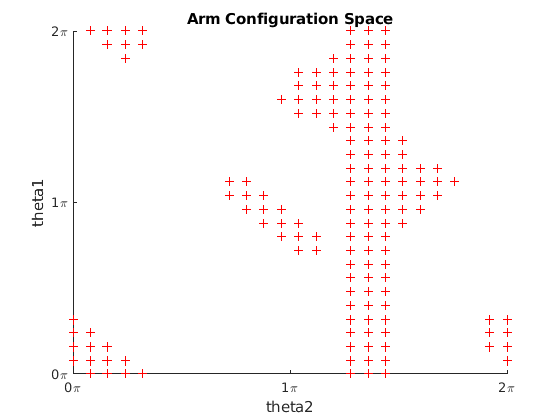

 
configuration_space_figure = figure();
title("Arm Configuration Space")
ylabel("theta1")
yticks((0:2*pi) * pi);
yticklabels( string(0:2*pi) + "\pi" )
xlabel("theta2")
xticks((0:2*pi) * pi);
xticklabels( string(0:2*pi) + "\pi" )
axis([0 2*pi 0 2*pi])
hold on;
config_space_collisions = space(1:2,space(5,:) == true);
plot(config_space_collisions(1,:), config_space_collisions(2,:),'+', 'MarkerFaceColor','red','MarkerEdgeColor','red');
hold off;

### Interactive Arm Control

Below is a demonstration of the arm moving through cartesian, task, and configuration spaces. Set the theta1 and theta2 values for the arm below and we will redraw the arm. In the cartesian space we draw a link as red if it has collided with something.

theta1 = 0.5* pi;
theta2 = 1.1* pi;
 

Let's draw the robot arm in place

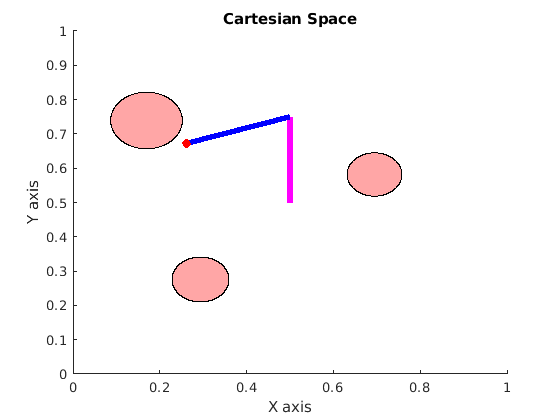

*Figure 8: An example of our robot arm moving in cartesian space*

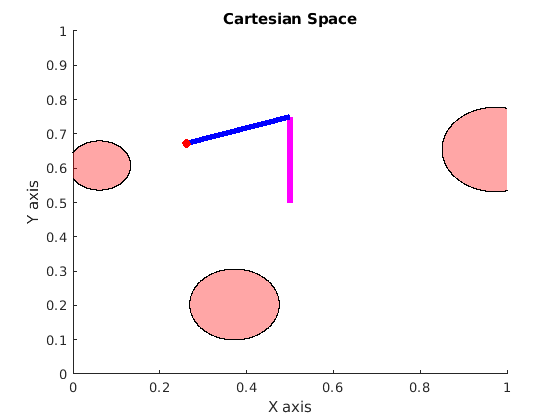

interactive1 = figure();
hold on;
for index = 1:length(obstacles)
    draw_obstacle(obstacles{index});
end
arm_lines = draw_robot_arm(theta1, theta2, obstacles);
j1 = [origin(1)+limb_length*cos(theta1); origin(2)+limb_length*sin(theta1) ];
j2 = [j1(1)+limb_length*cos(theta2); j1(2)+limb_length*sin(theta2) ];
plot(j2(1), j2(2), "o", "MarkerFaceColor", 'red', 'MarkerEdgeColor','red');
axis manual
axis([0 1 0 1])
title("Cartesian Space")
ylabel("Y axis")
xlabel("X axis")
hold off;

We also draw the task space, and mark with a red X where the end effector is. If the X is within the bounds of the complex shape created by blue dots, then the end effector is in a space that lacks collisions.

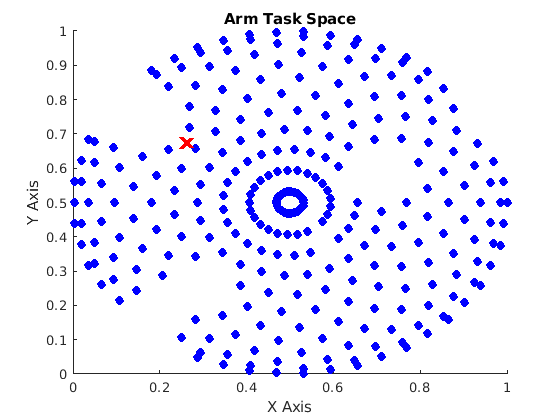

*Figure 9: An example of our end effector being represented in task space*

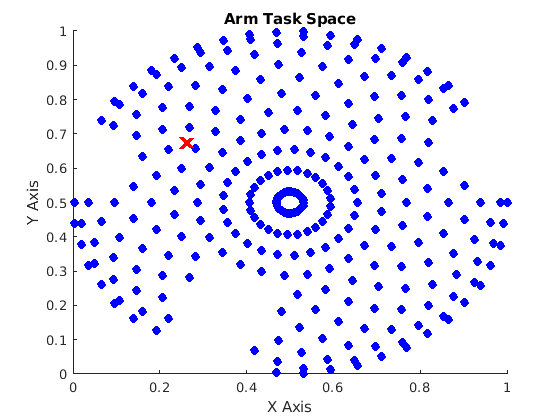

interactive2 = figure();
title("Arm Task Space")
ylabel("Y Axis")
xlabel("X Axis")
axis([0 1 0 1])
hold on;

task_free_spaces = space(3:4,space(5,:)==false);
plot(task_free_spaces(1,:), task_free_spaces(2,:), 'o', 'MarkerFaceColor','blue','MarkerEdgeColor','blue');
plot(j2(1), j2(2), "X", 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'red', 'LineWidth', 4, 'MarkerSize', 10);
hold off;

Finally we draw the config space and mark the current arm configuration with a black dot. You can imagine the next steps, which would be utilizing path planning to get between current and desired configurations to create a trajectory for the robot arm.

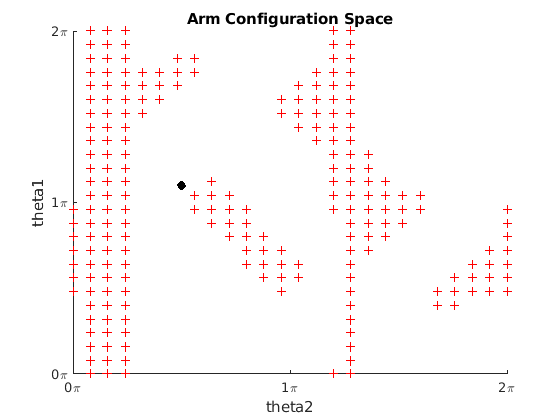

*Figure 10: An example of the given robot's configuration represented in configuration space*

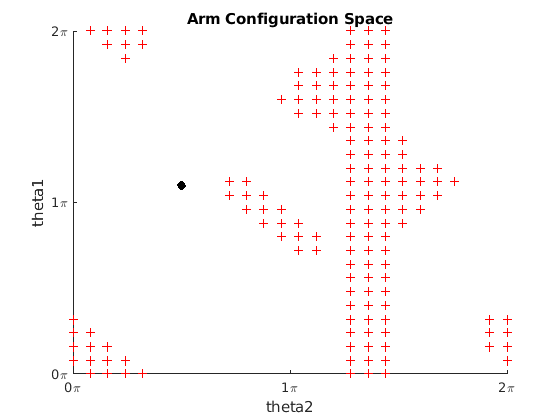

interactive3 = figure();
title("Arm Configuration Space")
ylabel("theta1")
yticks((0:2*pi) * pi);
yticklabels( string(0:2*pi) + "\pi" )
xlabel("theta2")
xticks((0:2*pi) * pi);
xticklabels( string(0:2*pi) + "\pi" )
axis([0 2*pi 0 2*pi])
hold on;
config_space_collisions = space(1:2,space(5,:) == true);
plot(config_space_collisions(1,:), config_space_collisions(2,:),'+', 'MarkerFaceColor','red','MarkerEdgeColor','red');
plot(theta1, theta2, "O", 'MarkerFaceColor', 'black', 'MarkerEdgeColor','black');
hold off;

### Functions

Here are a set of functions utilized to power the above code sections.

#### user_obstacle_draw

This function powers the interactive drawing and creation of obstacles at the beginning of our **Results** section. It tracks user clicks and creates circles per the user's specifications.

function user_obstacle_draw(hObject, ~)
    global active_center
    global obstacles

    axes_handle = gca;
    current_point = get(axes_handle, 'CurrentPoint');
    current_point = [current_point(1, 1); current_point(1, 2);];
    if active_center == false
       active_center = current_point;
       return
    else
        radius = sqrt( (active_center(1,1) - current_point(1,1))^2 + (active_center(2,1) - current_point(2,1))^2 );
        c = nsidedpoly(1000, 'Center', [active_center(1) active_center(2)], 'Radius', radius);
        plot(c, 'FaceColor', 'red')
        obstacles{end+1} = struct('center', active_center, 'radius', radius);
        active_center = false;
    end
end

#### mouse_move

This function is also used in the interactive portion, allowing the user to see the radius of the circle as they draw it.

function mouse_move(hObject, ~)
    global active_line
    if active_line ~= false
        delete(active_line)
        active_line = false ;    
    end
    global active_center
    if active_center ~= false
        axes_handle = gca;
        current_point = get(axes_handle, 'CurrentPoint');
        current_point = [current_point(1, 1); current_point(1, 2);];
        active_line = line('XData', [active_center(1) current_point(1)], 'YData', [active_center(2) current_point(2)], 'Color', 'magenta', 'LineWidth', 4);
    end
end

#### draw_robot_arm

Given theta1 and theta2 (and an optional cell array of obstacles) draw the robot arm. If the joints collide with any obstacles passed, color the arm as red.

function arm_lines = draw_robot_arm(theta1, theta2, obstacles)
    if nargin == 2
        obstacles = {};
    end
    limb_length = 0.25;
    origin = [0.5; 0.5];
    
    j1 = [origin(1)+limb_length*cos(theta1); origin(2)+limb_length*sin(theta1) ];
    j2 = [j1(1)+limb_length*cos(theta2); j1(2)+limb_length*sin(theta2) ];

    j1color = 'magenta';
    j2color = 'blue';
    
    if length(obstacles) > 0
        if collisions_for_joint(origin, j1, obstacles)
            j1color = 'red';
        end
        if collisions_for_joint(j1, j2, obstacles)
            j2color = 'red';
        end
    end
    
    arm_lines = {
        line('XData', [origin(1) j1(1)], 'YData', [origin(2) j1(2)], 'Color', j1color, 'LineWidth', 4),
        line('XData', [j1(1) j2(1)], 'YData', [j1(2) j2(2)], 'Color', j2color, 'LineWidth', 4)
    };
end

#### draw_obstace

A simple helper function to avoid repetitive code - given an obstacle (which is a struct of a cricle, used throughout this code base), draw it in the current active plot.

function draw_obstacle(obstacle)
    c = nsidedpoly(1000, 'Center', [obstacle.center(1) obstacle.center(2)], 'Radius', obstacle.radius);
    plot(c, 'FaceColor', 'red');
end

#### create_circle_form_points

Given two points of [X;Y;] coordinates, draw a circle whose edge touches both of these points. Useful for when creating the collision detectors.

function circle = create_circle_from_points(point1, point2)
    center = [ (point1(1)+point2(1))/2 , (point1(2)+point2(2))/2 ];
    radius = sqrt( (point1(1)-point2(1))^2 + (point1(2)-point2(2))^2 ) / 2;
    circle = struct('center', center, 'radius', radius);
end

#### limb_collision_circles

limb_collision_circles generates the set of circles for our collision detection for a given line from point a to be, to a set depth (default is 4). It organizes these circles on the return such that we can easily and predictively pull out circles of a set depth when we wish to check for collision.

function circles = limb_collision_circles(a, b, depth)
    if nargin < 3
        depth = 4;
    end
    depth = depth - 1;
    circles = {create_circle_from_points(a, b)};
    
    % If our depth is still not 0...
    if depth > 0
        % Let's go ahead and divide this into half, and create two more
        % sub-circles
        % Half 1
        midpoint = circles{1}.center;
        a_sub_circles = limb_collision_circles(a, midpoint, depth); % The midpoint is the center of our current circle
        % Half 2
        b_sub_circles = limb_collision_circles(midpoint, b, depth);
        % Interlace them and we should have a setup where I can easily
        % predict and grab
        % circles of the correct depth (IE grab the final layer of circles
        % for instance)
        target_a = true;
        while length(b_sub_circles) > 0
            if target_a
                circles{end+1} = a_sub_circles{1};
                a_sub_circles(1) = [];
                target_a = false;
            else
                circles{end+1} = b_sub_circles{1};
                b_sub_circles(1) = [];
                target_a = true;
            end
        end
    end
end

#### get_circles_of_depth

This function takes a cell array of circles created by limb_collision_circles and returns from it  all circles of the specified depth. This is used for checking increasing deeper levels of circles during collision checks.

function circles_of_depth = get_circles_of_depth(circles, depth)
    circles_of_depth = circles(2^(depth-1):(2^depth)-1);
end

#### circles_intersect

Given two circles in the struct format used throughout, check to see if the two circles intersect. This is as simple as comparing the distance between their centers vs the length of their radii.

function intersect = circles_intersect(a, b)
    distance = sqrt( (a.center(1)-b.center(1))^2 + (a.center(2)-b.center(2))^2 );
    
    intersect = a.radius+b.radius >= distance;
end

#### collisions_for_joint

This helper function takes a link, which consists of two points, and a list of obstacles. It then returns whether or not the joint collides with any of the obstacles.

function collision = collisions_for_joint(a, b, obstacles)
    collision = false;
    for obstacle = 1:length(obstacles)
        collision = joint_object_collision_check(a, b, obstacles{obstacle});
        if collision
            return
        end
    end
end

#### joint_object_collision_check

Given a link, consisting of two points, and an individual obstacle, go down the depth of collision detection circles. If, at any point, no circles of a depth are triggered, return that the link does not collide. If the 4th and final depth layer triggers a collison, then return that the link does collide with the object. Called within collisions_for_joint above.

function collision = joint_object_collision_check(a, b, object)
    collision = false;
    depth = 4;
    % Generate the circles for that joint
    circles = limb_collision_circles(a, b, depth);
    
    % Go through each depth
    for d = 1:depth
        depth_collision = false;
        % Get the current depth's circls
        current_circles = get_circles_of_depth(circles, depth);
        % Check to see if the current depth's circles intersect
        for c = 1:length(current_circles)
            depth_collision = circles_intersect(current_circles{c}, object);
            if depth_collision
                %If there is a collision, we no longer need to check this
                %depth
                break
            end
        end
        % If no collisions exist at a depth, we're done - there can't be
        % any at a higher depth value (closer to limb)
        if ~depth_collision
            return
        %If and only if there is a detected collision at depth of 4 do we
        %claim there's a collision
        elseif depth_collision && depth == 4
            collision = true;
            return
        end
    end
end

#### draw_circle

Helper function to avoid repetitive code - given a circle in the struct format, draw it within the current active plot.

function c = draw_circle(circle)
    c = nsidedpoly(1000, 'Center', [circle.center(1) circle.center(2)], 'Radius', circle.radius);
    plot(c, 'FaceColor', 'none', 'EdgeColor', 'green')
end

## Discussion

In this assignment, we explored observing the cartesian space, created collision detection, and then utilized this to generate a task and configuration spaces.

The collision detection method we utilized was powered by encompassing increasingly smaller chunks of a given link being encompassed by a circle, and testing if that circle intersects with our obstacles.

This allowed us to sweep our joints to build a task space which represents every possible endpoint the end effector can safely reach. This provides us an easy view into where our end effector for our robot arm can reach and work in.

We used the same information to record what theta values for our joints create collisions, and which don't. This allowed us to create a configuration space, which represents the range of all configurations of the robot which are safe given the current obstacles. This, combined with a path planning algorithm, can be used in the future to create safe trajectories for our robot arm despite the existence of obsacles in its path.

Finally, we demonstrated the robot arm moving throughout all three spaces with an interactive applet.